#    **Práctica 2 - Modelos Probabilísticos y Filtros Discretos**

#    *Robótica Móvil - Un enfoque probabilístico*

#    ***Alumno****: Brian Alex Fuentes Acuña.*

#    ***Padrón:**** 101785.*

## 1. Muestreo de distribuciones de probabilidad 

Implementar tres funciones en Octave/MATLAB que generen muestras de una distribución normal $N (µ, \sigma ^2 )$. Los parámetros de entrada de dichas funciones son la media $µ$ y la varianza $\sigma ^2$ de dicha distribución. Como única fuente de aleatoriedad, utilizar muestras de una distribución uniforme. 

**1).** En la primera función, generar las muestras de la distribución normal sumando muestras de 12 distribuciones uniformes. 

**Rta:** Se implementa la función *norm_uniform()* la cual da la distribución normal sumando 12 veces una muestra uniforme de a y finalmente se le suma la media $\mu $.

Nota: Los parámetros de entrada de la función pedida son $\mu $ y $\sigma^2$ pero adicionalmente se les pone un parámetro opcional, *param*, el cual nos da la opción de obtener un vector de "*param"*muestras en vez de sola una, esto con el fin de facilitar los gráficos.

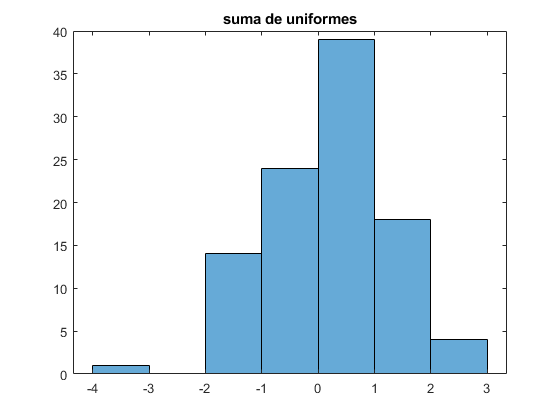

tic
m_norm= norm_uniform(0,1,100);
figure()
histogram(m_norm)
title('suma de uniformes')

toc

Elapsed time is 0.116931 seconds.


**2).** En la segunda función, usar “muestreo con rechazo” 

**Rta:** Para obtener lo pedido se hace uso de una función gaussiana en donde norm_mrech() devuelve muestras que no hayan sido rechazadas.

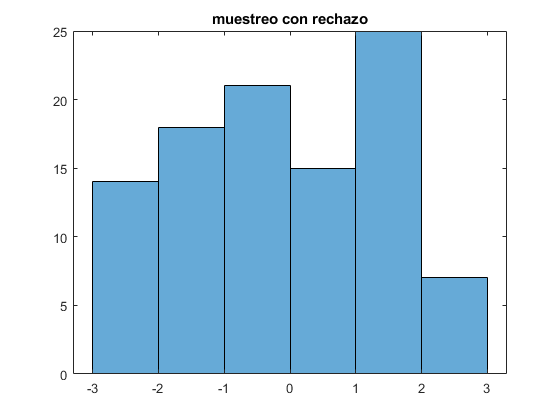

tic
r_norm = norm_mrech(0, 1,100);
figure()
histogram(r_norm)
title('muestreo con rechazo')

toc

Elapsed time is 0.173975 seconds.


**3).** En la tercera función, usar el método de la transformación de Box-Muller. El método de Box-Muller permite generar muestras de una distribución normal usando dos muestras uniformemente distribuidas u1, u2 ∈ [0, 1] según la ecuación:

                
$$x= cos(2 \pi u_1)\sqrt{-2log u_2}$$


**Rta:** Se usó el método tal cual como aparece en la ecuación, para obtener la media y la varianza que se le pase como parámetros a la función, se hace uso de la siguiente propiedad $Z' = Z.\sigma + \mu$.

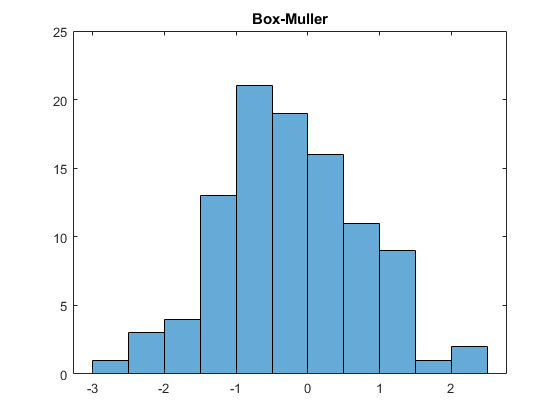

tic
norm = norm_boxMuller(0, 1,100);
histogram(norm)   
title('Box-Muller')

toc

Elapsed time is 0.296974 seconds.


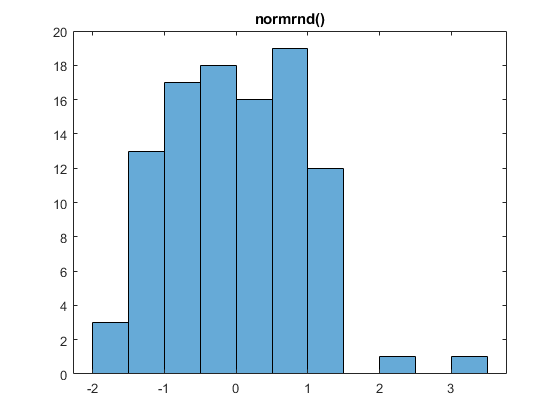

tic
figure()
histogram(normrnd(0,1, [1, 100]))
title('normrnd()')

toc

Elapsed time is 0.090789 seconds.


Adicionalmente se muestra con *normrand() *propia de matlab.

Entonces se han comparado para cada método con 100 muestras y se han comparado los tiempos que tardaron en ejecutarse 100 veces para una una normal estándar.

Aunque dependiendo de la ejecución puede tardar mas o menos tiempo. se ha obtenido:

0.1208[Seg] para el método de suma de uniformes.

0.1223[Seg] para el método de muestreo con rechazo.

0.2595[Seg] para el método de Box-Müller.

0.0787[Seg] para normrand().

En general los tiempos rondan por esos valores, pero lo interesante es ver que el método del muestreo con rechazo y el de suma de uniformes son más rápidos de entre los implementados y tienen casi el mismo tiempo.

sin embargo, el metodo de Box-Muller es quien peor tiempo tiene de todos los métodos, esto puede deberse a que tiene funciones "complejas" como el coseno y raiz cuadrada.

Quien mejor tiempo tiene de todo los métodos es el que brinda matlab, normrnd(), el cual es notablemente más rápido. y nos da valores visualmente fieles a una normal, aunque las demás implementaciones también lo hacen, el método de muestreo con rechazo a veces no arroja muestras fieles a una normal.

*nota: puede deverse a una mala implementación.*

## 2. Modelo de movimiento basado en odometría

Implementar un modelo de movimiento basado en odometría siguiendo estos pasos: 

**1).** Crear una función en Octave/MATLAB que implemente un modelo de movimiento basado en odometr´ıa. los tres argumentos de entrada deberán ser:

                   
$$x_t = \pmatrix{x \cr y \cr \theta}
$$
        
$$
u_t = \pmatrix{\delta_{r1} \cr \delta_{r2}  \cr \delta_{t} }

$$
        
$$\alpha = \pmatrix{\alpha_1 \cr \alpha_2 \cr \alpha_3 \cr \alpha_4}
$$
 

Donde $x_t$ es la pose actual del robot, ut es la lectura de odometría obtenida por los sensores del robot y $\alpha$ son los parámetros de ruido del modelo de movimiento. La función deberá devolver la nueva pose del robot $x_t+1$. 

La implementación de la función deberá incluir el error de obtención   de la odometría. Usar los métodos de muestreo del ejercicio 1 para generar muestras aleatorias normalmente distribuidas para introducir ruido en el modelo de movimiento.

**Rta:**  Se ha creado la función *[x_p, y_p, theta_p]= sample_motion_odometria(ut, xt, alpha, f_distribución);*

el cual calcula todo lo pedido y recibe los parámetros pedidos, pero adicionalmente tiene el parámetro *f_distribucion* el cual sirve para ingresarlo la funciones de distribución implementadas en el ejercicio 1 y así facilitar los gráficos del siguiente inciso.

**2)** Evaluar el modelo de movimiento desarrollado generando 5000 muestras con los siguientes argumentos:

                        
$$x_t = \pmatrix{2,0 \cr 4,0 \cr 0,0}
$$
        
$$
u_t = \pmatrix{ \pi/2 \cr 0,0  \cr 1,0 }

$$
        
$$\alpha = \pmatrix{0,1\cr 0,1 \cr 0,01 \cr 0,01}
$$


Graficar las posiciones $(x_t+1, y_t+1)$ para las 5000 muestras en un solo gráfico.

**Rta: **Se proceden a graficar las 5000 muestras pedidas para el modelo de odometria en donde las muestras de ruido se implementan con normrand().

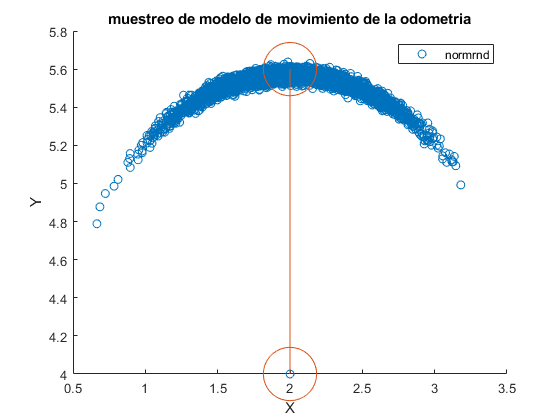

xt= [2;4;0];
ut= [pi/2; 0; 1];
alpha= [0.1; 0.1; 0.01; 0.01];
X= zeros(3,5000);
X(:,1)= xt;

for i=2:5000
    [x_p, y_p, theta_p]= sample_motion_odometria(ut, xt, alpha);   
    X(:,i)= [x_p, y_p, theta_p]';
end
%normrnd.
h1= figure();
hold on
scatter(X(1,:), X(2,:));
plot([X(1,1) X(1,1)], [X(2,1) 5.6], 'o-', 'MarkerSize',40);
title("muestreo de modelo de movimiento de la odometria")
legend('normrnd')
xlabel("X")
ylabel("Y")

Ahora se hace lo mismo, pero usando el método de Box-Muller

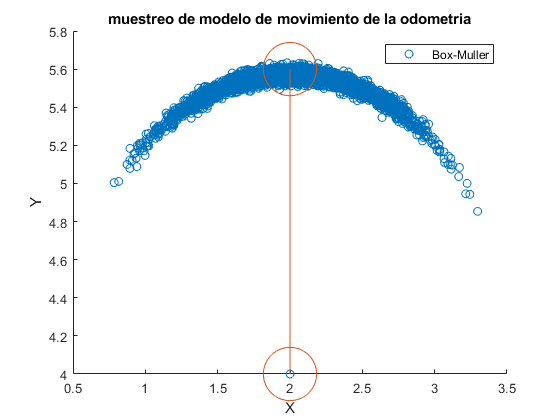


%norm: Box-Muller
for i=2:5000
    [x_p, y_p, theta_p]= sample_motion_odometria(ut, xt, alpha, @norm_boxMuller);   
    X(:,i)= [x_p, y_p, theta_p]';
end
%
h2= figure();
hold on
scatter(X(1,:), X(2,:));
plot([X(1,1) X(1,1)], [X(2,1) 5.6], 'o-', 'MarkerSize',40)
title("muestreo de modelo de movimiento de la odometria")
legend('Box-Muller')
xlabel("X")
ylabel("Y")

Con la función norm_uniform(), el metodo de suma de uniformes.

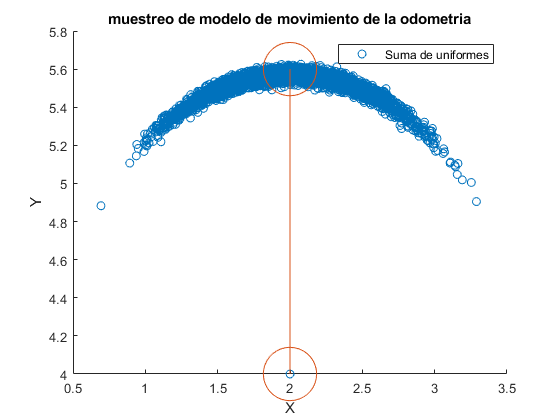

%norm: Suma de uniformes
for i=2:5000
    [x_p, y_p, theta_p]= sample_motion_odometria(ut, xt, alpha, @norm_uniform);   
    X(:,i)= [x_p, y_p, theta_p]';
end
%
h3= figure();
hold on
scatter(X(1,:), X(2,:));
plot([X(1,1) X(1,1)], [X(2,1) 5.6], 'o-', 'MarkerSize',40)
title("muestreo de modelo de movimiento de la odometria")
legend('Suma de uniformes')
xlabel("X")
ylabel("Y")

Y finalmente con norm_mrech() el método de muestreo con rechazo. 

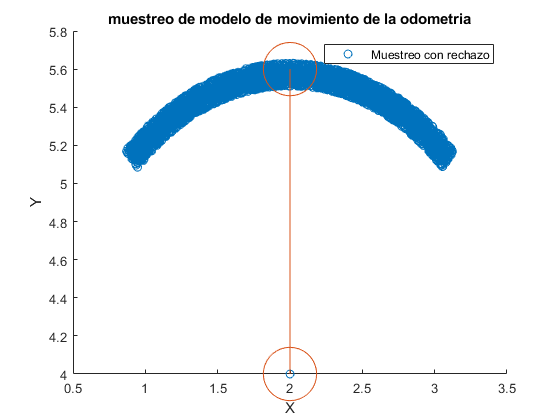

%norm: Muestreo con rechazo.
for i=2:5000
    [x_p, y_p, theta_p]= sample_motion_odometria(ut, xt, alpha, @norm_mrech);   
    X(:,i)= [x_p, y_p, theta_p]';
end
%
h4= figure();
hold on
scatter(X(1,:), X(2,:));
plot([X(1,1) X(1,1)], [X(2,1) 5.6], 'o-', 'MarkerSize',40)
title("muestreo de modelo de movimiento de la odometria")
legend('Muestreo con rechazo')
xlabel("X")
ylabel("Y")
hold off

Notar que todos los métodos, a excepción del último, nos dan una "luna" de probabilidad para el siguiente paso y todas parecen ser que tienen mayor probabilidad en el medio, lo cual es coherente con la teoría.

Estas formas indican cual es la probabilidad de terminar en alguna de esas posiciones dado que se estaba en $x_{t-1}$. 

Notar que los desplazamientos en *Y* dentro de usos puntos indica un error de traslación y la apertura radial tiene que ver con el error de rotación, en general se observa que el error de traslación es menor al de rotación.

Sin embargo el ultimo grafico muestra que el modelo de odometria implementado con el método de muestreo por rechazo tiene probabilidades similares en los extremos, es decir que el movimiento al siguiente paso puede ser cualquiera con básicamente la misma probabilidad, esto indica que el modelo implementado con este método es un mal modelo, pero también puede ser una mala implementación de la función.

## 3. Filtro Discreto 

Queremos estimar la posición de un robot que se mueve en un mundo unidimensional acotado. El mundo tiene 20 celdas y el robot se encuentra inicialmente en la celda 10 (siendo la primer celda es la celda 0 y la ultima la 19). El robot no puede salir del area especificada. 

En cada paso, el robot puede ejecutar el comando ‘avanzar un paso’ o ‘retroceder un paso’. Este movimiento puede tener cierto error, por lo que el resultado puede no siempre ser el esperado. De hecho, el robot se comporta de la siguiente manera: al ejecutar ‘avanzar un paso’ el resultado será el siguiente:

el 25 % de las veces, el robot no se moverá 

el 50 % de las veces, el robot avanzará una celda 

el 25 % de las veces, el robot se moverá dos celdas 

el robot en ningún caso se moverá en el sentido opuesto o avanzará más de dos celdas. 

**Rta**: el algortimo a implementar será el siguiente:

*            1. Algoritmo Filtro_de_Bayes (*$Bel(x), d$*):*

*            2. *$\eta$*=0 *

*            3. If d is a perceptual data item z then *

*            4. For all x do *

*            5.          *$Bel'(x)= P(z|x)Bel(x)$

*            6.          *$\eta = \eta + Bel'(x)$

*            7. For all x do *

*            8.          *$Bel'(x) = \eta ^{-1}Bel'(x)$

*            9. Else if d is an action data item u then *

*            10. For all x do *

*            11.        *$Bel'(x)= \sum P(x|u,x')Bel(x')$

*            12. Return *$Bel’(x)$

En donde se debe notar que nos están pidiendo solamente el modelo de acción es decir la la belief estimada la acción *u*.

Entonces se pide la línea 11 del algoritmo planeado inicialmente en donde para cada celda será:

*Bel'(x=0)= P(x=0 | u, x'=0).Bel(x'=0) + P(x=0 | u, x'=1).Bel(x'=1) + .....+ P(x=0 | u, x'=19).Bel(x'=19).*

*Bel'(x=1)= P(x=1 | u, x'=0).Bel(x'=0) + P(x=1 | u, x'=1).Bel(x'=1) + .....+ P(x=1 | u, x'=19).Bel(x'=19).*

*            ...*

*Bel'(x=19)= P(x=19 | u, x'=0).Bel(x'=0) + P(x=19 | u, x'=1).Bel(x'=1) + .....+ P(x=19 | u, x'=19).Bel(x'=19).*

entonces veamos como simplificar esto:

suponiendo *u= 'avanzar un paso'*. y teniendo en cuenta las probabilidades dadas por el enunciado.

*Bel'(x=0)= P(x=0 | u, x'=0).Bel(x'=0) + P(x=0 | u, x'=1).Bel(x'=1) + .....+ P(x=0 | u, x'=19).Bel(x'=19).*

*Bel'(x=0)= P(x=0 | u, x'=0).Bel(x'=0) +                 0                      + .....+                 0                         .*

 puesto que existe la probabilidad de estar en el estado de estar en 0 y quedarse en cero pero no las de estar en 0 y haber estado en 1 a 19, implicaría moverse en sentido opuesto.

*Bel'(x=1)= P(x=1 | u, x'=0).Bel(x'=0) + P(x=1 | u, x'=1).Bel(x'=1) + .....+ P(x=1 | u, x'=19).Bel(x'=19).*

*Bel'(x=1)= P(x=1 | u, x'=0).Bel(x'=0) + P(x=1 | u, x'=1).Bel(x'=1) +0+ .....+                 0    *                 .

puesto que P(x=1 | u, x'=1:19) implicaría moverse adelante más de dos pasos.

entonces en general para los estados no particulares y la acción de moverse adelante se tiene:

*Bel'(x= i)= P(x= i | u, x'= i).Bel(x'= i) + P(x= i | u, x'= i-1).Bel(x'= i-1) + P(x =i | u, x'= i-2).Bel(x'= i-2).*

analogamente para *u= 'retroceder un paso'*

*Bel'(x= i)= P(x= i | u, x'= i).Bel(x'= i) + P(x= i | u, x'= i+1).Bel(x'= i+1) + P(x =i | u, x'= i+2).Bel(x'= i+2).*

entonces se implementa la función [bel] = Filtro_de_bayes(bel, d) que devuelve la bel(x) para todas las celdas

y asi calcular las probabilidades a posteri dada la belief a priori y las nueve acciones de avanzar con 3 de retrocer.

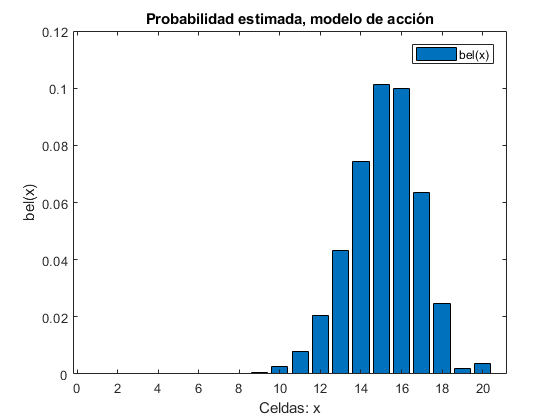

bel=[zeros(10, 1); 1; zeros(9, 1)];
for i=1:12
    if i <= 9
        d= 'avanzar'; %notar que los avnaces no estan haciendo nada!!!!!!.
    else
        d= 'retroceder';
    end
    
    [bel] = Filtro_de_bayes(bel, d);
    bar(bel);
    legend('bel(x)')
    title('Probabilidad estimada, modelo de acción')
    xlabel('Celdas: x')
    ylabel('bel(x)')
    %pause(1)
end

Notar que si estoy en la celda 10 y avanzo 9 pasos para luego retroceder 3 debería de terminar en la celda 16. pero mi grafico muestra valores de 1 a 20 por lo que debería estar en la celda 17. y claramente se ve que tiene mayor probabilidad de estar en la celda 15, es una mala estimación de la POSE del robot.

Esto no quiere decir que el modelo está mal, está incompleto puesto que se debe corregir la belief con muestras medidas por algún sensor (como sugiere el algoritmo completo).

De no ser así se tendría la cinemática resuelta y no haría falta medir la POSE del robot todo el tiempo, bastaría con calcularla.

funciones:

function norm = norm_uniform(mu, var, param)
    %Devuelve una normal N~(mu, sigma) generada a partir de pseudouniformes
    %Param=0 defaault, Param=n devuelve n muestras distribuidas. 
    %assert(var >=1, 'la varianza debe ser mayor a 1.')
    
    if nargin < 3
        n= 1;
        norm= 0;
    else
        n= param;
        norm= zeros(1,n);
    end

    a= -var;
    b=  var;
    %uniforme en el intervalo (a,b):= uniform = a + (b-a).*rand(1)

    for i=1:12
        uniform = a + (b-a).*rand(1,n);
        norm= norm + uniform;
    end
    norm= norm/2 + mu; %le sumo la media tal que ~N(0,sigma)->~N(mu, sigma)
end

function norm = norm_mrech(mu, var, param)
    %Devuelve una normal N~(mu, sigma) 
    %Param=0 defaault, Param=n devuelve n muestras distribuidas.   
    if nargin < 3
        n= 1;
        norm= 0;
    else
        n= param;
        norm= zeros(1,n);
    end
    
    %function gaussiana, ,camapana de gauss.
    for i= 1:n
        norm(i)= sample_in_distribution(@normpdf, mu, var);
    end
    
end

function norm = sample_in_distribution(f, mu, b_)
    %devuelve una muestra aleatoria por debajo de la funcion f.
    max_f= f(mu,mu,b_);% / xE[-b,b]   
    a = -3*b_;
    b =  3*b_;     %pasaalgo con los sigma en el grafico.
    norm = 0;
    %uniforme en el intervalo (a,b):= uniform = a + (b-a).*rand(1)
    %do while.
    idx= 0;
    while true
        %muestra aleatoria entre a y b.
        x = a + (b - a).*rand(1);
        %muestra aleatoria entre 0 y max(f)
        y = max_f*rand(1); 
        %
        if (y <= f(x, mu, b))
            norm= x;
            break;
        end
        assert(idx < 1000, 'se ha exedido el tiempo de iteracion_sample_in_distribution');    
        idx= idx + 1;
    end
    %
end
%normpdf
function [y]= Camp_gauss(x, mu, var) 
    y= (exp(-(x-mu)^2/(2*var)))/sqrt(2*pi*var);
end


function [norm] = norm_boxMuller(mu, var, param)
    
    if nargin < 3
        n= 1;
        norm= 0;
    else
        n= param;
        norm= zeros(1,n);
    end

    u1= rand(1,n);
    u2= rand(1,n);
    
    for i= 1:n
        norm(i) = cos(2*pi.*u1(i)) * sqrt( -2.*log( u2(i) ) );
    end
    norm = var.*norm + mu;
end


function [x_p, y_p, theta_p]= sample_motion_odometria(u, x_, alpha, f)
    %PONER CASOS PARTICULARES
    if nargin < 4
        sample= @(mu,var) normrnd(mu,var);
    else
        sample= f;
    end
    
    
    %defino variables.
    drt1= u(1); drt2= u(2); dtrs= u(3);
    x= x_(1);   y= x_(2);   theta= x_(3);
    a1= alpha(1); a2= alpha(2); a3= alpha(3); a4= alpha(4);
    
    drt1_p= drt1  + sample(0, a1*abs(drt1) + a2*abs(dtrs));
    dtrs_p= drt1  + sample(0, a3*abs(dtrs) + a4*( abs(dtrs)+abs(drt2) ));
    drt2_p= dtrs  + sample(0, a1*abs(drt1) + a2*abs(dtrs));
    
    x_p = x + dtrs_p*cos(theta + drt1_p);
    y_p = y + dtrs_p*sin(theta + drt1_p);
    theta_p =   theta + drt1_p + drt2_p;
end

function [bel_xp] = Filtro_de_bayes(bel, d)

    %Avanzar un paso:
    P.px0_Mov_x0= 1/4; %el 25 % de las veces, el robot no se moverá
    P.px1_Mov_x0= 1/2; %el 50 % de las veces, el robot avanzará una celda
    P.px2_Mov_x0= 1/4; %el 25 % de las veces, el robot se moverá dos celdas
    P.pxn_Mov_x0= 0; %el robot en ningún caso se moverá en el sentido opuesto o avanzará más de dos celdas
    
    %Retroceder un paso:
    P.px0_Ret_x0= 1/4; %el 25 % de las veces, el robot no se moverá
    P.pxn1_Ret_x0= 1/2; %el 50 % de las veces, el robot retrodederá una celda
    P.pxn2_Ret_x0= 1/4; %el 25 % de las veces, el robot se retrodederá dos celdas
    P.pxnn_Ret_x0= 0; %el robot en ningún caso se moverá en el sentido opuesto o retrodederá más de dos celdas      
        
    %Casos borde: avanzar.
    P.px19_Mov_x19= 1; %si el robot está en la última celda, al tratar de avanzar se quedará en la misma celda el 100 % de las veces
    %si el robot está en la penúltima celda, 
    % al tratar de avanzar se quedará en la misma celda el 25 % de las veces,
    % y se moverá a la próxima celda el 75 % de las veces.
    P.px18_Mov_x18= 1/4;
    P.px19_Mov_x18= 3/4;
    %Casos borde: retroceder.
    P.px0__Ret_x0= 1;
    P.px1_Ret_x1= 1/4;
    P.px0_Ret_x1= 3/4;
    
    bel_xp= zeros(length(bel),1);
    
    %moverser_adelante 
    if strcmp(d, 'avanzar')
            bel_xp(1)= P.px0_Mov_x0*bel(1);
            bel_xp(2)= P.px0_Mov_x0*bel(2);
        for i = 3:18
            bel_xp(i) = P.px0_Mov_x0*bel(i) + P.px1_Mov_x0*bel(i-1) + P.px2_Mov_x0*bel(i-2);
        end
            bel_xp(20) = P.px19_Mov_x19*bel(20) + P.px19_Mov_x18*bel(19);
            bel_xp(19) = P.px18_Mov_x18*bel(19) +  P.px1_Mov_x0*bel(18);%+ P.px19_Mov_x18*bel(19);
     %retroceder
    elseif strcmp(d, 'retroceder')
            bel_xp(1)= P.px0__Ret_x0*bel(1) + P.px0_Ret_x1*bel(2)+ P.pxn2_Ret_x0*bel(3);
            bel_xp(2)= P.px1_Ret_x1*bel(2) + P.pxn1_Ret_x0*bel(3)+ P.pxn2_Ret_x0*bel(4);
        for i = 3:18
           bel_xp(i)= P.px0_Ret_x0*bel(i) + P.pxn1_Ret_x0*bel(i+1) + P.pxn2_Ret_x0*bel(i+2);
        end
            bel_xp(19)= P.px0_Ret_x0*bel(19);
            bel_xp(20)= P.px1_Ret_x1*bel(20);
    else
            bel_xp= bel;
            assert(falta,'opccion incorrecta');
    end  
    
end